close  all;clear;
addpath("D:\matlab\data of project2");
%load data_1.mat to data_1.mat
idx_start_time =1;
load(sprintf('data_%d.mat',idx_start_time));

%raw时域图
seq_ref = [seq_ref, seq_ref];
seq_sur = [seq_sur, seq_sur];

t = linspace(0, 2 * duration, length(seq_ref));

%raw频域图
ref_fft = fft(seq_ref) / length(seq_ref);
ref_fft_shift = fftshift(ref_fft);

sur_fft = fft(seq_sur) / length(seq_sur);
sur_fft_shift = fftshift(sur_fft);

%DDC
%时域
f_mid = 2120e6;
ref_shift = seq_ref .* exp(j * -f_mid * t);
sur_shift = seq_sur .* exp(j * -f_mid * t);

%频域
%shift之后要不要转回频域做滤波
ref_shift_fft = fft(ref_shift) / length(ref_shift);
ref_shift_fft_shift = fftshift(ref_shift_fft);

sur_shift_fft = fft(sur_shift) / length(sur_shift);
sur_shift_fft_shift = fftshift(sur_shift_fft);

%低通
% 找低通滤波器系数
[b_low, a_low] = butter(8, 10e6/(f_s/2));

% 找单位频率响应
ref_shift_LP = filter(b_low,a_low,ref_shift); %滤的时候是输入时频上的信号？？
sur_shift_LP = filter(b_low,a_low,sur_shift); 

%频域
ref_shift_LP_fft = fft(ref_shift_LP) / length(ref_shift_LP);
ref_shift_LP_fft_shift = fftshift(ref_shift_LP_fft);

sur_shift_LP_fft = fft(sur_shift_LP) / length(sur_shift_LP);
sur_shift_LP_fft_shift = fftshift(sur_shift_LP_fft);

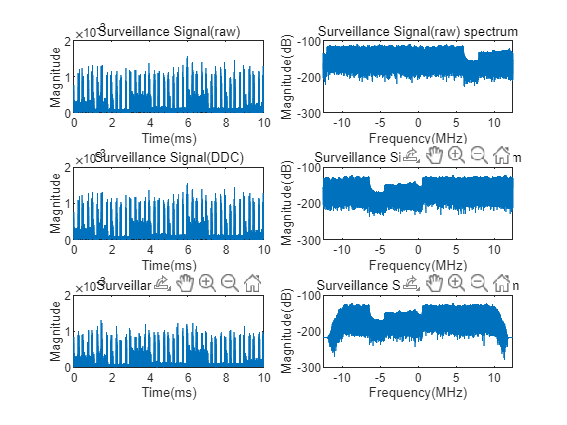

figure(1);
myPlot(t, seq_sur, sur_fft_shift, "Surveillance", "raw", 1);
myPlot(t, sur_shift, sur_shift_fft_shift, "Surveillance", "DDC", 3);
myPlot(t, sur_shift_LP, sur_shift_LP_fft_shift, "Surveillance", "LPF", 5);

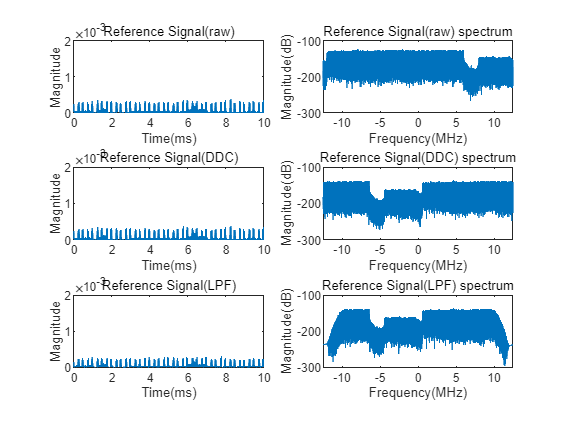

figure(2);
myPlot(t, seq_ref, ref_fft_shift, "Reference", "raw", 1);
myPlot(t, ref_shift, ref_shift_fft_shift, "Reference", "DDC", 3);
myPlot(t, ref_shift_LP, ref_shift_LP_fft_shift, "Reference", "LPF", 5);